## MSE 491 DSP - Lab Assignment 2

Authors:

- Abdullah Amjad - 301414558

- Tony Nguyen - 301286979

Created: 15 June 2022

Modified: 21 June 2022

clear all
close all
clc

## Loading Variables

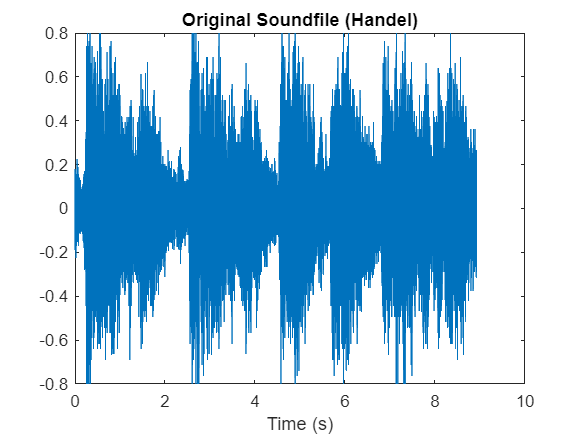

% Loading audio
% Import carrier signal
global y Fs Ts N t current previous
load Handel

Ts = 1/Fs;
N = length(y);
t = [0:N-1]*Ts; t = t(:);
current = y;

%sound(y,Fs)
figure
plot(t,y);title('Original Soundfile (Handel)');
xlabel('Time (s)');

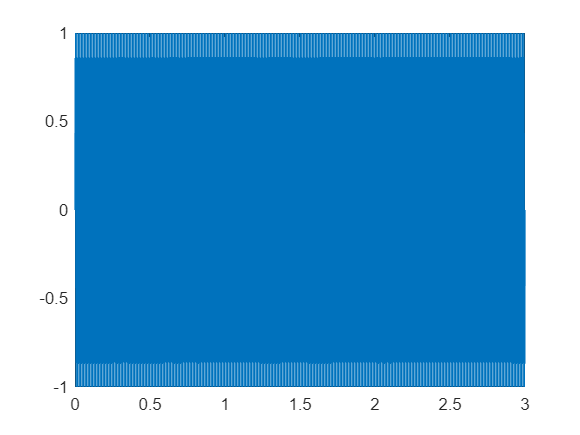

% Alternate audio loading - Sine wave that is easier to visualize audio effects
global y Fs Ts N t current previous

Fs = 48000;
Ts = (1/Fs);
t = 0:Ts:3;
t = t(:);
f = 100; phi = 0;
y = sin(2*pi*f.*t + phi);
N = length(y);
current = y;

figure(1);
plot(t,y);

## Fade-in/out

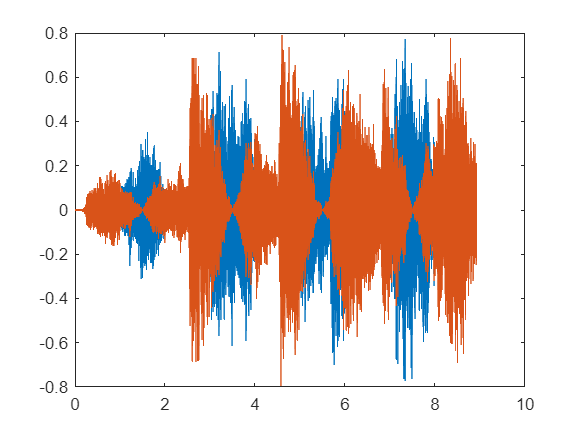

% Fade-in/out: the user can set a fade-in/out in volume effect. The type of fade is 
% user-selectable between linear fade, or exponential fade. The start and stop time 
% of the fade effect is user-selectable with reasonable default values. 
fadeTime = 3;
curveType = 0;
fadeType = 0;

current = fade(current, Fs, fadeTime, curveType, fadeType);

figure
plot(t,current)

### Linear Fade

% a = linspace(0,1,fadeN); a = a(:); %1 in linspace is the volume of fade in/out, do not change
% fadeIn = a;
% fadeOut = 1-a; % Equivalent = linspace(1,0,numOfSamples);
% 
% % %For testing
% % figure(2); 
% % plot(fadeTime*a,fadeIn,fadeTime*a,fadeOut);legend('Fade-in','Fade-out');

% % Linear Fade–in
% % Index samples just at the start of the signal
% current(1:fadeN) = fadeIn.* current(1:fadeN);
% 
% %For testing
% %soundsc(current, Fs);
% 
% figure;
% plot(t,current)

% % Linear Fade–out
% % Index samples just at the end of the signal
% current(end-fadeN+1:end) = fadeOut.*current(end-fadeN+1:end);
% 
% %For testing
% % soundsc(current, Fs);
% 
% figure;
% plot(t,current);

### Exponential Fade

% % Variable setup
% fadeTime = 1.5; %user-selectable
% fadeN = fadeTime*Fs;
% x = 2; % Exponent for curve, will leave at 2 for now

#### Convex Fades

% a = linspace(0,1,fadeN); a = a(:);
% fadeOut = 1 - a.^x;
% 
% a = linspace(1,0,fadeN); a = a(:);
% fadeIn = 1 - a.^x;
% 
% % For Testing
% % figure(2);
% % plot(fadeTime*a,fadeIn,fadeTime*a,fadeOut);legend('Fade–in','Fade–out');

% % Convex Fade–in
% current(1:fadeN) = fadeIn.* current(1:fadeN);
% 
% soundsc(current, Fs);
% figure(3);
% plot(t,current);

% % Convex Fade–out
% current = current;
% current(end-fadeN+1:end) = fadeOut.*current(end-fadeN+1:end);
% 
% soundsc(current, Fs);
% figure(4);
% plot(t,current);

#### Concave Fades

% a = linspace(0,1,fadeN); a = a(:);
% CavExpFadeOut = a.^x;
% 
% a = linspace(1,0,fadeN); a = a(:);
% CavExpFadeIn = a.^x;
% 
% figure(5);
% plot(fadeTime*a,CavExpFadeIn,fadeTime*a,CavExpFadeOut);legend('Fade In','Fade Out');

% % Concave Fade–in
% temp = y;
% temp(1:fadeN) = CavExpFadeIn .* y(1:fadeN);
% 
% soundsc(temp, Fs);
% figure(3);
% plot(t,temp);

% % Convex Fade–out
% current = temp;
% current(end-fadeN+1:end) = CavExpFadeOut.*temp(end-fadeN+1:end);
% 
% soundsc(current, Fs);
% figure(4);
% plot(t,current);

## Tremelo

% Tremolo parameters input by user;
depth = 100; %user definable; intensity of effect: chamged amplitude and offset; ranges from [0,100]%
f = 3; %user definable; frequency of effect; ranges from [0.1,20] Hz
waveType = 1; %user definable; select between sine, square, triange, sawtooth
phi = 0; %set by user? is this needed?

amp = 0.5*(depth/100);
offset = 1 - amp;

%select wavetype
switch waveType
    case 0
        sw = sin(2*pi*f.*t+phi); % sin wave
    case 1
        sw = square(2*pi*f.*t+phi); % square wave
    case 2
        sw = sawtooth(2*pi*f.*t+phi, 0.5); % triangle wave; set 'xmax' to 0.5 in sawtooth function
    case 3
        sw = sawtooth(2*pi*f.*t+phi); % sawtooth wave
end 

mod = amp.*sw + offset;

% to delete
% Plot to compare the original wave with the modulator
% Index only first second of signal for visualization purposes
% figure
% plot(t(1:Fs),sw(1:Fs),t(1:Fs),mod(1:Fs));
% legend('OG','Modulated');
% title('Modulator Signal');

% Modulate the amplitude of the carrier by the modulator
current = current.*mod;

% Plot the output and listen to the result

% sound(output,Fs);
figure
plot(t,current);
% title('Output Signal (Processed)');

## Rythmic Auto Panning

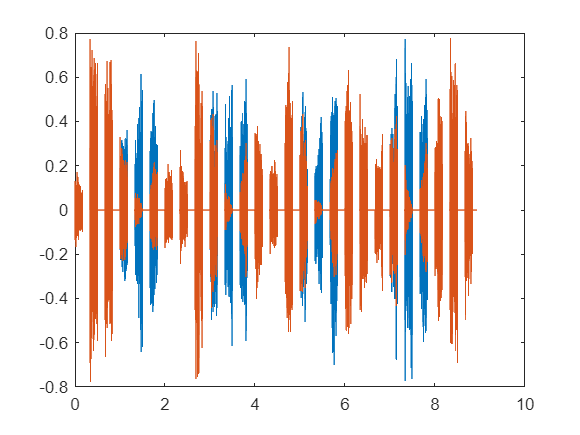

% AUTOPANEXAMPLE
% This script implements the automatic panning (auto–pan)
% effect. The function "pan" is used to process an
% input signal, along with an array of pan values
% for each sample number in the signal
%
% See also PAN
% Input Variables
% panType : 1 = linear, 2 = sqRt, 3 = sine–law
% panValue : (–100 to +100)


% User inputted variables
f = 0.5; % Frequency of panning LFO
panAmp = 100; % Intensity of effect

% Generate sine wave LFO based on f and t
panValue = panAmp*sin(2*pi*f*t);
panType = 2; % Start with panType = 2, but try 1,2,3

% Run pan function
[current] = pan(current,panValue,panType);

% figure
% plot(t,current(:,1))
% title('Left Channel Output');
% 
% figure
% plot(t,current(:,2),"Color",[0.8500 0.3250 0.0980])
% title('Right Channel Output');

%sound(current,Fs);
figure
plot(t,current);

## Echo

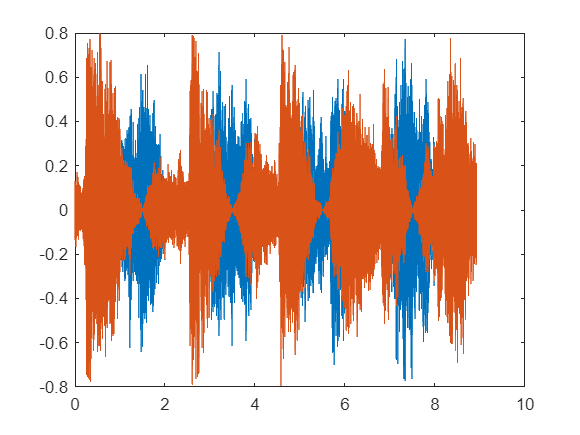

% ECHOFEEDBACK
% This script demonstrates one example to create a
% feedback, tempo–synchronized echo effect
%
% See also ECHOSYNC

% Known tempo of recording
beatsPerMin = 102; % units of beats per minute

% Calculate beats per second
beatsPerSec = beatsPerMin / 60; % 1 minute / 60 seconds

% Calculate # of seconds per beat

secPerBeat = 1/beatsPerSec;

% Note division 
% User-selectable from list below
% 4 = whole, 2 = half, 1 = quarter, 0.5 = 8th, 0.25 = 16th
noteDiv = 0.25;

% Calculate delay time in seconds
timeSec = noteDiv * secPerBeat;

% Convert to units of samples
d = fix(timeSec * Fs); % round to nearest integer sample

a = -0.75; % amplitude of delay branch

% Index each element of our signal to create the output
x = zeros(N,2);

for n = 1:N
% When the sample number is less than the time delay
% Avoid indexing a negative sample number
    if n < d+1
        % output = input
        x(n,1) = current(n,1);
        
        if width(current) == 2
            x(n,2) = current(n,2);
        end        
        % Now add in the delayed signal
    else
        % output = input + delayed version of output
        % reduce relative amplitude of delay to 3/4
        x(n,1) = current(n,1) + (-a)*x(n-d,1);
        
        if width(current) == 2
            x(n,2) = current(n,2) + (-a)*x(n-d,2);
        end
    end
end

current = x;

sound(current,Fs); % Listen to the effect
figure
plot(t,current)

## Reverb

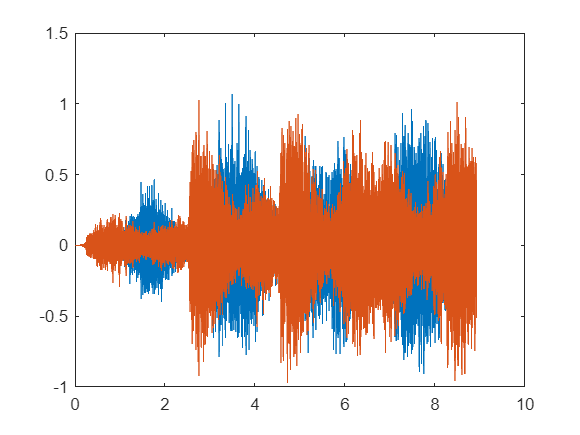

% REVERBCONV
% This script demonstrates the process to create
% a stereo convolution reverb by using a two–channel
% impulse response. This impulse response is based
% on a measurement of a recording studio
% in Nashville, Tennessee.

% Import sound file and IR measurement
[h] = audioread('reverbIR.wav'); % Stereo IR

% Visualize one channel of the impulse response
plot(h(:,1));


% Perform convolution
Left = conv(current,h(:,1));
Right = conv(current,h(:,2));

current = [Left,Right];
N = length(current);
t = [0:N-1]*Ts; t = t(:);

sound(current,Fs);

Functions

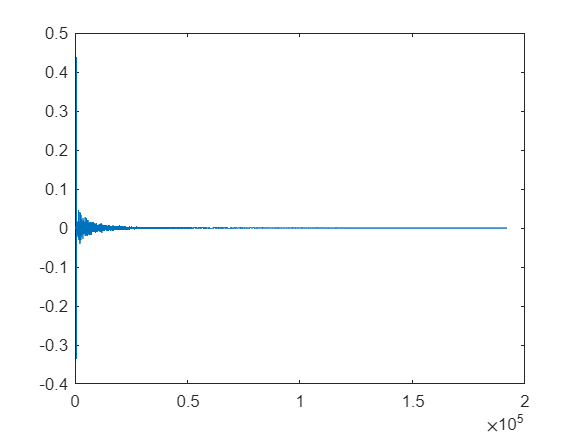

% Performs fade audio effect on inputted audio waveform
%
% Input variables
% in: input audio signal
% Fs: sampling frequency

% fadeTime: legnth of fade in seconds
% curveType: 0 = linear, 1 = exponential
% fadeType: 0 = fade-in, 1 = fade-out

Error using conv
A and B must be vectors.

function [out] = fade(in, Fs, fadeTime, curveType, fadeType)
    %variable initialization
    fadeN = fadeTime*Fs; %number of effected samples for fade
    a = linspace(0,1,fadeN);
    a = a(:); %transpose
    x = 2;%exponent of curve; user definable?

    %linear or exponential fade?
    switch curveType
        case 0 %linear
            fadeIn = a;
            fadeOut = a-1;
        case 1 %exponential
            fadeOut = 1 - a.^x;

            a = linspace(1,0,fadeN); a = a(:);
            fadeIn = 1 - a.^x;
    end
    
    %fade in or out?
    switch fadeType
        case 0 % in
            in(1:fadeN,1) = fadeIn.*in(1:fadeN,1);
            
            if width(in) == 2 
                in(1:fadeN,2) = fadeIn.*in(1:fadeN,2);
            end
        case 1 % out
            in(end-fadeN+1:end,1) = fadeOut.*in(end-fadeN+1:end,1);
            if width(in) == 2
                in(end-fadeN+1:end,2) = fadeOut.*in(end-fadeN+1:end,2);
            end
    end

    out = in;
end

% PAN
% This function pans a mono audio signal in a stereo field.
% It is implemented such that it can pan the entire signal
% to one location if "panValue" is a scalar. It can also be
% used for auto–pan effects if "panValue" is an array.
%
% Input Variables
% panType : 1 = linear, 2 = sqRt, 3 = sine–law
% panValue : (–100 to +100) transformed to a scale of (0–1)

function [out] = pan(in, panValue, panType)
% Convert pan value to a normalized scale
    panTransform = (panValue/200) + 0.5;
    
    % Conditional statements determining panType
    switch panType
        case 1
            leftAmp = 1 - panTransform;
            rightAmp = panTransform;
        case 2
            leftAmp = sqrt(1 - panTransform);
            rightAmp = sqrt(panTransform);
        case 3
            leftAmp = sin((1 - panTransform) * (pi/2));
            rightAmp = sin(panTransform * (pi/2));
    end
    
    leftChannel = leftAmp.*in;
    rightChannel = rightAmp.*in;
    
    out = [leftChannel,rightChannel];

end